# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves the stochastic life cycle model using backward induction.

%}

## Model: Stochastic Life Cycle Model.

The representative consumer is born in period $0$ and lives up to $T-1$. Her working life is from period $0$ to $t_r-1$, where she receives exogenous labor income, $y_t$. From period $t_r$ onward, she is retired and receives a pension equal to some fraction, $0<\kappa<1$, of her labor income in the last period of her working life. She maximizes lifetime utility by choosing consumption and savings, subject to a dynamic budget constraint in each period. Her optimization problem is:


$$\underset{\{c_t\}_{t=1}^{T-1},\{a_{t+1}\}_{t=0}^{T-1}}{\text{max }} \mathbb{E}_0\left(U\right) =  \mathbb{E}_0\left[\sum_{t=1}^{T-1} \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma}\right] \text{ ,}$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


for all $t = 0, 1, ..., T-1$ and where $|\rho|<1$ and $\epsilon_t\sim\mathcal{N}(0,\sigma^2)$. The consumer has an initial wealth endowment, $a_0\geq0$, and the real interest rate, $r$, is fixed. You will gradually extend, solve, and simulate this model. When simulating the model, initialize the state variables, including age: for the endogenous state variables, assume equal probabilities for each state; for any exogenous Markov process, draw from the stationary distribution. In each simulation, you must have a panel of 1000 consumers over 30 periods. 

## Recursive Formulation.

The recursive formulation  is


$$V_t(a_t,t,y_t) = \underset{c_t, a_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_0\left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$


 
$$\text{s.t. } a_{t+1} = (1+r)(a_t+y_t-c_t)  \ , $$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


The state space consists only of $a_t$ while the choice space consists of $c_t$ and $a_{t+1}$. Substituting the budget constraint into the utility function gives


$$V_t(a_t,t,y_t) = \underset{a_{t+1}}{\text{max}}\frac{\left[a_t+y_t-\frac{a_{t+1}}{1+r}\right]^{1-\sigma}}{1-\sigma} + \beta \left[V_{t+1}(a_{t+1},t+1,y_{t+1})\right] \ ,$$



$$y_t = \begin{cases}
		\text{exp}(\rho \ \text{log} \ y_{t-1} + \epsilon_t) & \ \text{if} \ t<t_r \\
		\kappa y_{t_r-1} & \ \text{if} \ t\geq t_r
	\end{cases} \ , $$



$$a_0 \ \text{given} \ ,$$



$$a_T = 0 \ , \\ 
c_t > 0 \ ,  $$


which reduces the choice space to $a_{t+1}$.

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\ThinkBook\OneDrive - Fulbright University Vietnam\Desktop\code ps2\Matlab q1\Stochastic_export\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\ThinkBook\OneDrive - Fulbright University Vietnam\Desktop\code ps2\Matlab q1\Stochastic_export\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

The grid for assets is set exogenously.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Backward Induction.

Calls: solve.m and model.m.

We will solve the model using backward induction. In the last period of life, it is optimal to consume everything


$$c_T = a_T + y_T \ .$$


t = cputime;
sol = solve.lc(par); % Solve the model using Backward Induction.

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.4844 seconds.


## Simulate the model and plot the policy functions.

Calls: simulate.m and my_graph.m.

Simulate a population with heterogeneous age.

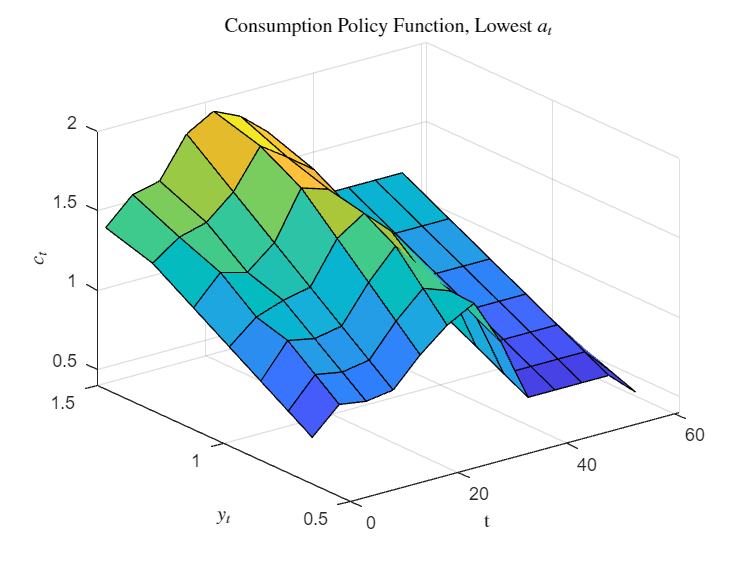

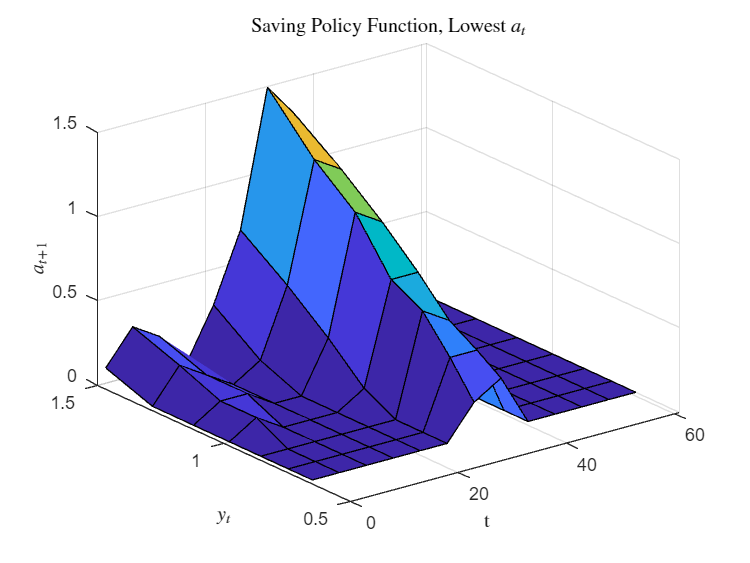

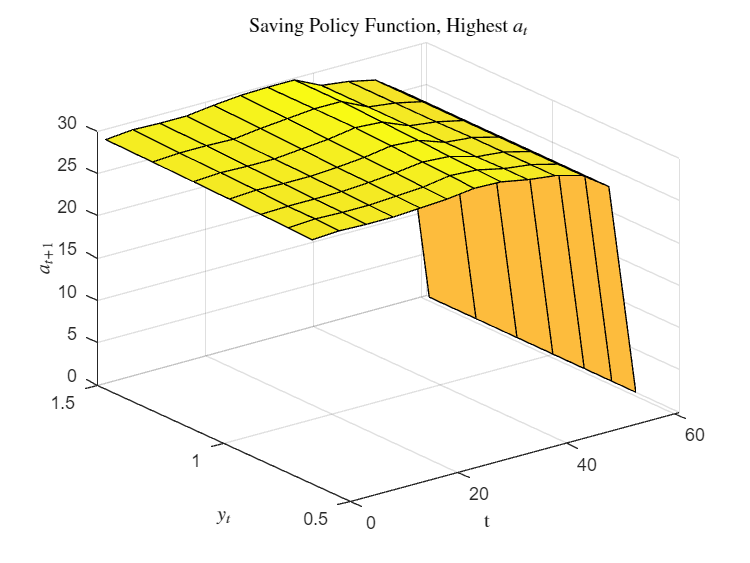

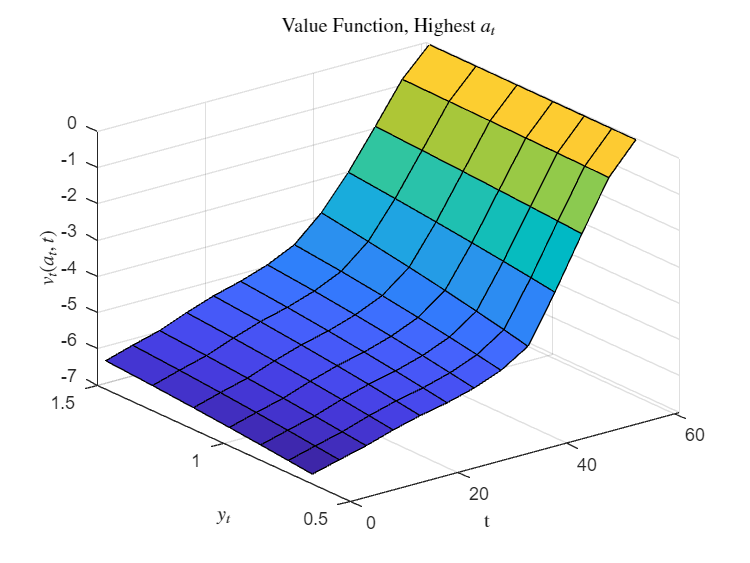

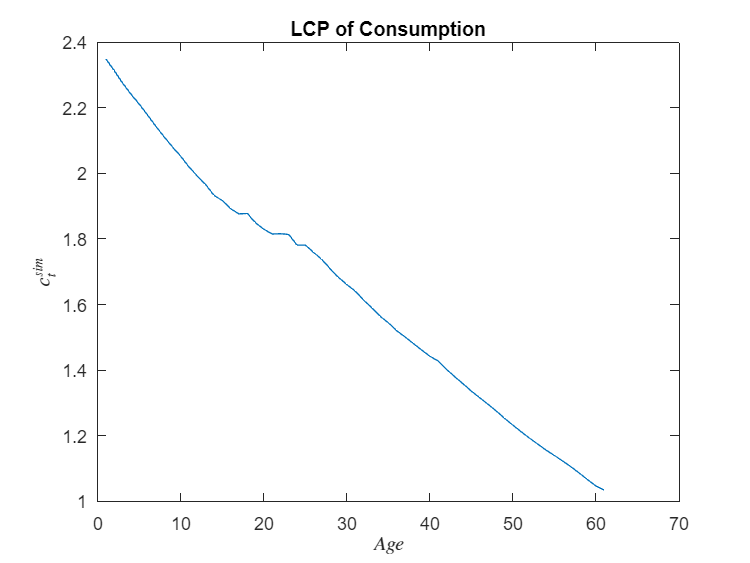

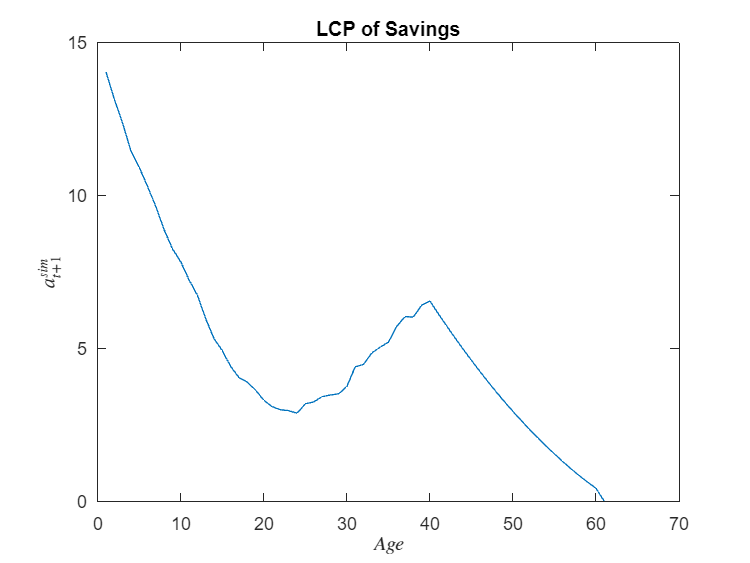

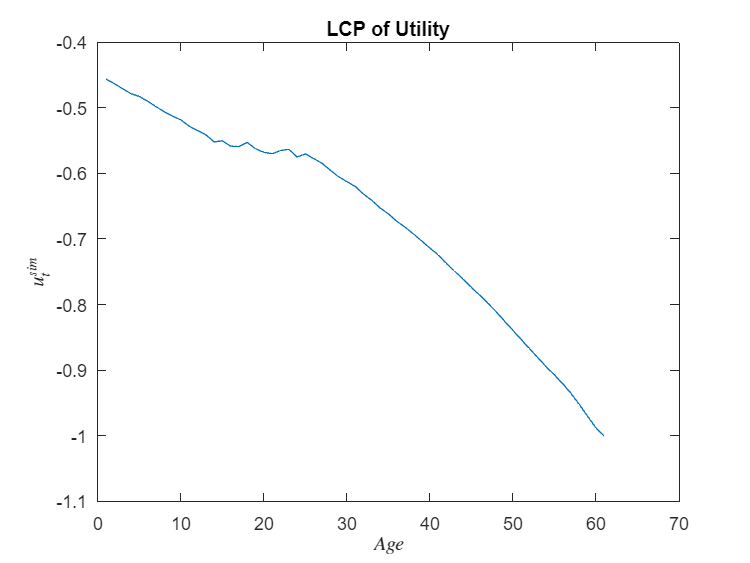

sim = simulate.lc(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim) % Plot the model functions and time series.

% Parameters
betas = [0.90, 0.92, 0.94, 0.96];
gamma = 2.00;
age = 1:61;
colors = lines(length(betas)); % Color palette

% Matrix to store average consumption by age for each beta
cons_matrix = nan(length(age), length(betas));

% === Figure 1: Consumption Profiles ===
figure; hold on;
for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma;
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average consumption for each age
    avg_c = nan(par.T, 1);
    for t = age
        avg_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end

    % Store for summary stats
    cons_matrix(:, i) = avg_c;

    % Plot consumption profile
    plot(age, avg_c, 'LineWidth', 1.5, ...
        'DisplayName', sprintf('\\beta = %.2f', betas(i)), ...
        'Color', colors(i, :));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


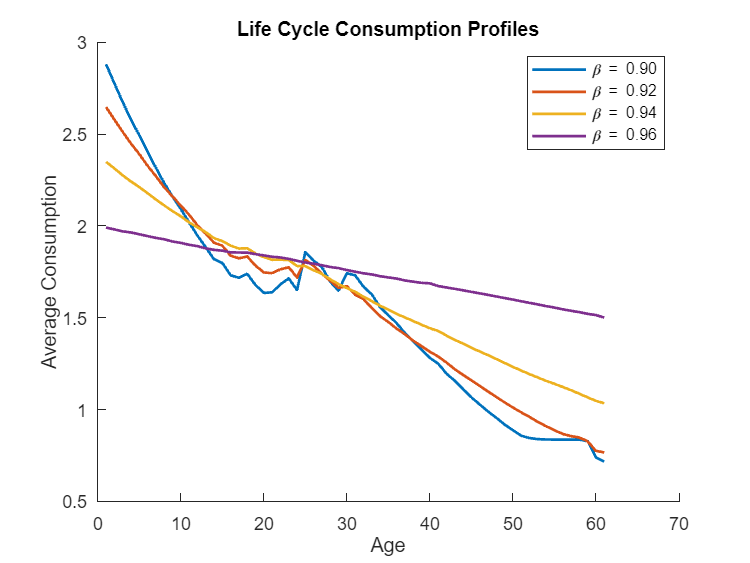

xlabel('Age'); ylabel('Average Consumption');
legend('Location', 'northeast');
title('Life Cycle Consumption Profiles');


% === Descriptive Stats Table (Mean, Std, Min, Max) ===
means = mean(cons_matrix, 1, 'omitnan');
stds  = std(cons_matrix, 0, 1, 'omitnan');
mins  = min(cons_matrix, [], 1);
maxs  = max(cons_matrix, [], 1);

desc_table = table(betas', means', stds', mins', maxs', ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Consumption ===');

=== Descriptive Summary of Consumption ===


disp(desc_table);

    Beta     Mean       Std        Min       Max  
    ____    ______    _______    _______    ______

     0.9    1.5459    0.55875    0.71627    2.8804
    0.92    1.5669    0.50794    0.76649    2.6465
    0.94    1.6334    0.37153     1.0341    2.3483
    0.96    1.7482     0.1403     1.5007    1.9908




% === Figure 2: Wealth Profiles ===
figure; hold on;
for i = 1:length(betas)
    % Initialize parameters
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma; % Corrected gamma value
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average wealth for each age
    avg_a = nan(par.T,1);
    for t = age
        avg_a(t) = mean(sim.asim(sim.tsim==t), 'omitnan');
    end

    % Plot wealth for this beta
    plot(age, avg_a, 'LineWidth', 1.5, 'DisplayName', sprintf('\\beta = %.2f', betas(i)), 'Color', colors(i,:));

    
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


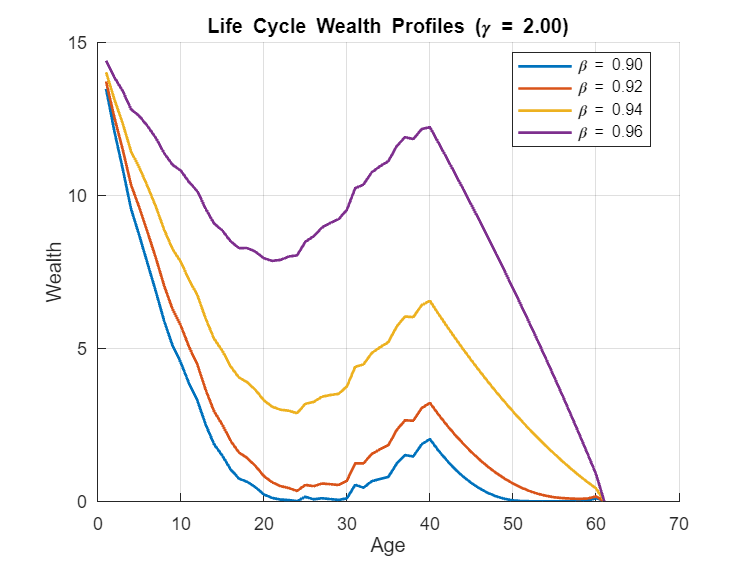

xlabel('Age'); ylabel('Wealth');
title('Life Cycle Wealth Profiles (\gamma = 2.00)');
legend('Location', 'best'); grid on;

% === Build Wealth Matrix ===
wealth_matrix = nan(length(age), length(betas)); % Rows: ages, Columns: beta values

for i = 1:length(betas)
    % Initialize and simulate
    par = model.setup();
    par.beta = betas(i);
    par.gamma = gamma;
    par = model.gen_grids(par);
    
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);
    
    % Fill matrix with average wealth by age
    for t = age
        wealth_matrix(t, i) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% === Descriptive Stats Table for Wealth (Mean, Std, Min, Max) ===
means_w = mean(wealth_matrix, 1, 'omitnan');
stds_w  = std(wealth_matrix, 0, 1, 'omitnan');
mins_w  = min(wealth_matrix, [], 1);
maxs_w  = max(wealth_matrix, [], 1);

desc_table_wealth = table(betas', means_w', stds_w', mins_w', maxs_w', ...
    'VariableNames', {'Beta', 'Mean', 'Std', 'Min', 'Max'});

format shortG
disp('=== Descriptive Summary of Wealth ===');

=== Descriptive Summary of Wealth ===


disp(desc_table_wealth);

    Beta     Mean      Std      Min     Max  
    ____    ______    ______    ___    ______

     0.9    1.9598    3.2394     0     13.476
    0.92    2.6787     3.341     0     13.717
    0.94    4.9629      3.12     0     14.024
    0.96    8.9061    3.2099     0     14.393



% Parameters
beta = 0.96;  % Only beta = 0.96
gammas = [2.00, 3.00, 4.00, 5.00];  % Different gamma values
age = 1:61;
colors = lines(length(gammas));  % Color palette

avg_c = nan(length(gammas), 100);
avg_a = nan(length(gammas), 100);

% === Figure 1: Consumption Profiles ===
figure; hold on;
for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Update gamma for each plot
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average consumption for each age
    avg_c = nan(par.T, 1);
    for t = age
        avg_c(t) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end

    % Plot consumption for this gamma and beta
    plot(age, avg_c, 'LineWidth', 1.5, 'DisplayName', sprintf('\\gamma = %.2f', gammas(g)), 'Color', colors(g, :));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


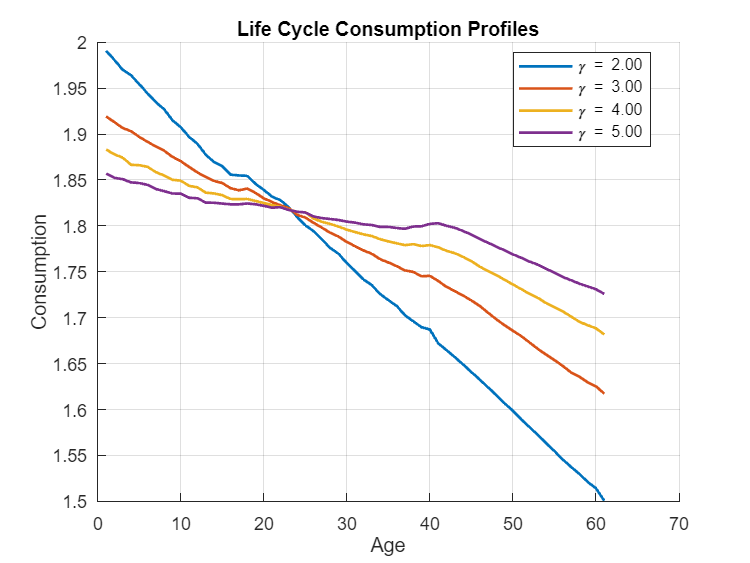

xlabel('Age'); ylabel('Consumption');
title('Life Cycle Consumption Profiles');
legend('Location', 'best'); grid on;

gammas = [2.00, 3.00, 4.00, 5.00];  % use this instead of `gamma`
cons_matrix_gamma = nan(length(age), length(gammas)); % size = 61 x 4

for g = 1:length(gammas)
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Vary gamma correctly
    par = model.gen_grids(par);

    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    for t = age
        cons_matrix_gamma(t, g) = mean(sim.csim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


G = size(cons_matrix_gamma, 2);
gamma_vec = gammas(:);
means_g = mean(cons_matrix_gamma, 1, 'omitnan')';
stds_g  = std(cons_matrix_gamma, 0, 1, 'omitnan')';
mins_g  = min(cons_matrix_gamma, [], 1)';
maxs_g  = max(cons_matrix_gamma, [], 1)';

desc_table_gamma = table(gamma_vec, means_g, stds_g, mins_g, maxs_g, ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});

disp(desc_table_gamma)

    Gamma     Mean       Std        Min       Max  
    _____    ______    ________    ______    ______

      2      1.7482      0.1403    1.5007    1.9908
      3      1.7757    0.084927    1.6173    1.9192
      4      1.7912    0.053608    1.6817    1.8832
      5      1.8016    0.033163    1.7258    1.8568



% Parameters
beta = 0.96;
gammas = [2.00, 3.00, 4.00, 5.00];
age = 1:61;
colors = lines(length(gammas)); % Unique colors for each gamma

% === Figure: Wealth Profiles ===
figure; hold on;
for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Update gamma for each plot
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Calculate average wealth for each age
    avg_a = nan(par.T, 1);
    for t = age
        avg_a(t) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end

    % Plot wealth line for this gamma
    plot(age, avg_a, 'LineWidth', 1.5, 'DisplayName', sprintf('\\gamma = %.2f', gammas(g)), ...
         'Color', colors(g, :));
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------


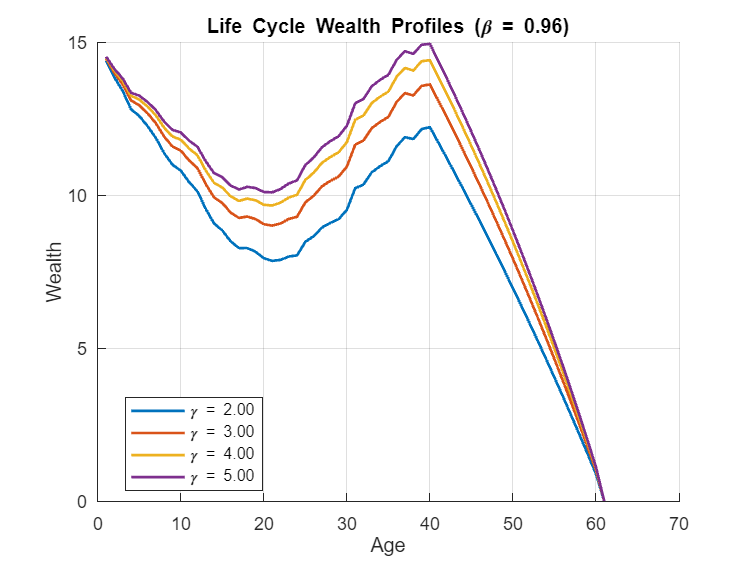

xlabel('Age'); ylabel('Wealth');
title('Life Cycle Wealth Profiles (\beta = 0.96)');
legend('Location', 'best'); grid on;

% === Initialize matrix to store avg. wealth by age for each gamma ===
wealth_matrix_gamma = nan(length(age), length(gammas)); % Rows: age, Columns: gamma values

for g = 1:length(gammas)
    % Initialize parameters
    par = model.setup();
    par.beta = beta;
    par.sigma = gammas(g);  % Gamma varies here
    par = model.gen_grids(par);

    % Solve model and simulate
    sol = solve.lc(par);
    sim = simulate.lc(par, sol);

    % Store average wealth by age
    for t = age
        wealth_matrix_gamma(t, g) = mean(sim.asim(sim.tsim == t), 'omitnan');
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------



% === Descriptive Stats Table (Mean, Std, Min, Max) for Wealth ===
means_w = mean(wealth_matrix_gamma, 1, 'omitnan')';
stds_w  = std(wealth_matrix_gamma, 0, 1, 'omitnan')';
mins_w  = min(wealth_matrix_gamma, [], 1)';
maxs_w  = max(wealth_matrix_gamma, [], 1)';

desc_table_wealth = table(gammas(:), means_w, stds_w, mins_w, maxs_w, ...
    'VariableNames', {'Gamma', 'Mean', 'Std', 'Min', 'Max'});

% Display the table
format shortG
disp('=== Descriptive Summary of Wealth by Gamma ===');

=== Descriptive Summary of Wealth by Gamma ===


disp(desc_table_wealth);

    Gamma     Mean      Std      Min     Max  
    _____    ______    ______    ___    ______

      2      8.9061    3.2099     0     14.393
      3      9.8474    3.3647     0     14.466
      4      10.381    3.4725     0     14.503
      5      10.737    3.5526     0     14.946



% Parameters
betas = [0.90, 0.92, 0.94, 0.96];
gammas = [2.00, 3.00, 4.00, 5.00];
age = 1:61;

% Preallocate matrix to store average wealth
avg_wealth_matrix = nan(length(betas), length(gammas));

% Loop over all combinations of beta and gamma
for b = 1:length(betas)
    for g = 1:length(gammas)
        % Initialize parameters
        par = model.setup();
        par = model.gen_grids(par);
        par.beta = betas(b);
        par.sigma = gammas(g);
        

        % Solve model and simulate
        sol = solve.lc(par);
        sim = simulate.lc(par, sol);

        % Compute average wealth across all simulated individuals
        avg_wealth = mean(sim.asim(:), 'omitnan');        
        % Store result
        avg_wealth_matrix(b, g) = avg_wealth;
    end
end

------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.
Age: 30.
Age: 25.
Age: 20.
Age: 15.
Age: 10.
Age: 5.
------------Life Cycle Problem Solved.------------
------------Solving from the Last Period of Life.------------

Age: 60.
Age: 55.
Age: 50.
Age: 45.
Age: 40.
Age: 35.

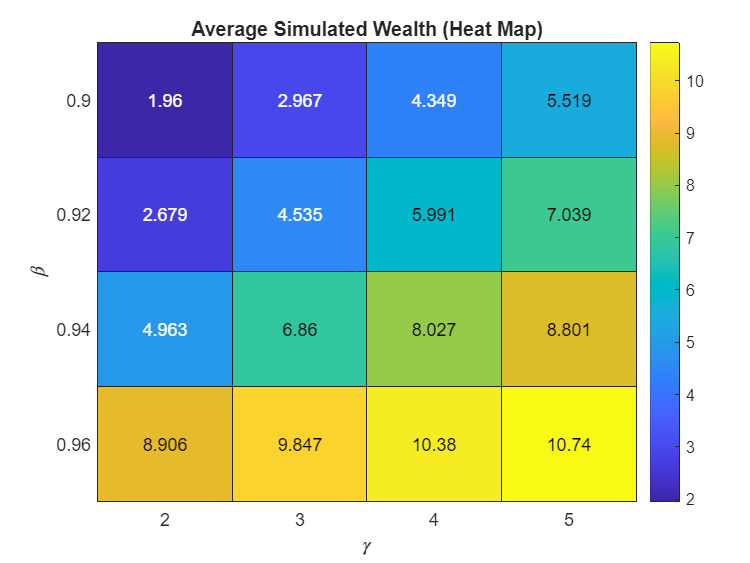


% === Plot Heatmap ===
figure;
h = heatmap(string(gammas), string(betas), avg_wealth_matrix, 'Colormap', parula);
xlabel('\gamma'); ylabel('\beta');
title('Average Simulated Wealth (Heat Map)');